# EE105 Lab 6 Fluids

# Name: Buddy Ugwumba SID: 862063029

1. Draw and label the equivalent circuit. Ignore inertia of the fluid flowing within the pipes. **(5'')**

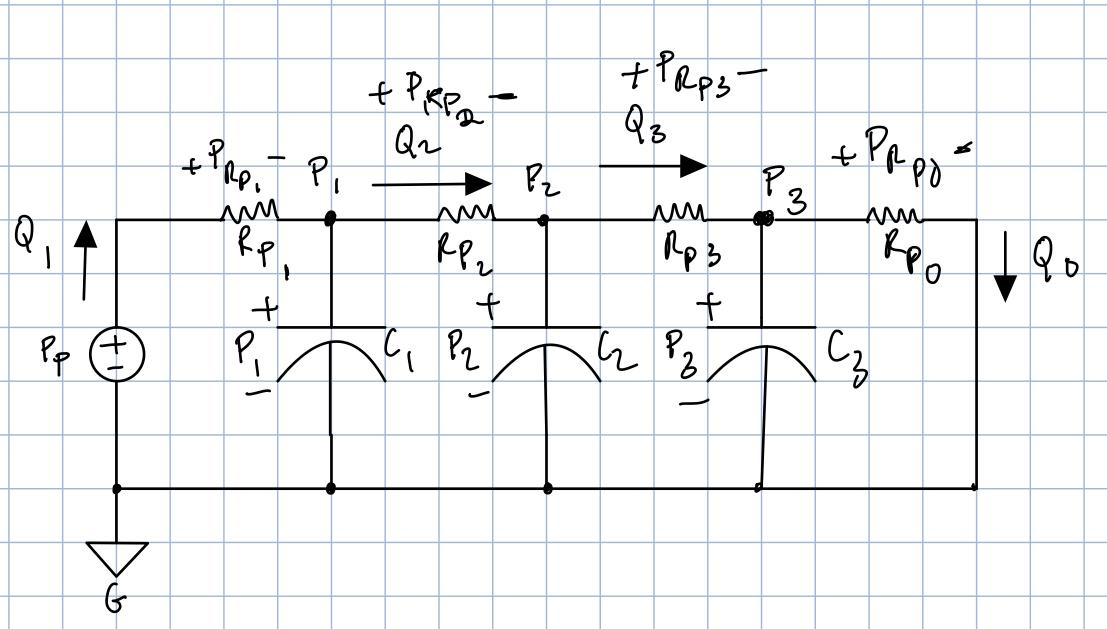

2.  Construct and simplify a bond graph model. **(5'')**

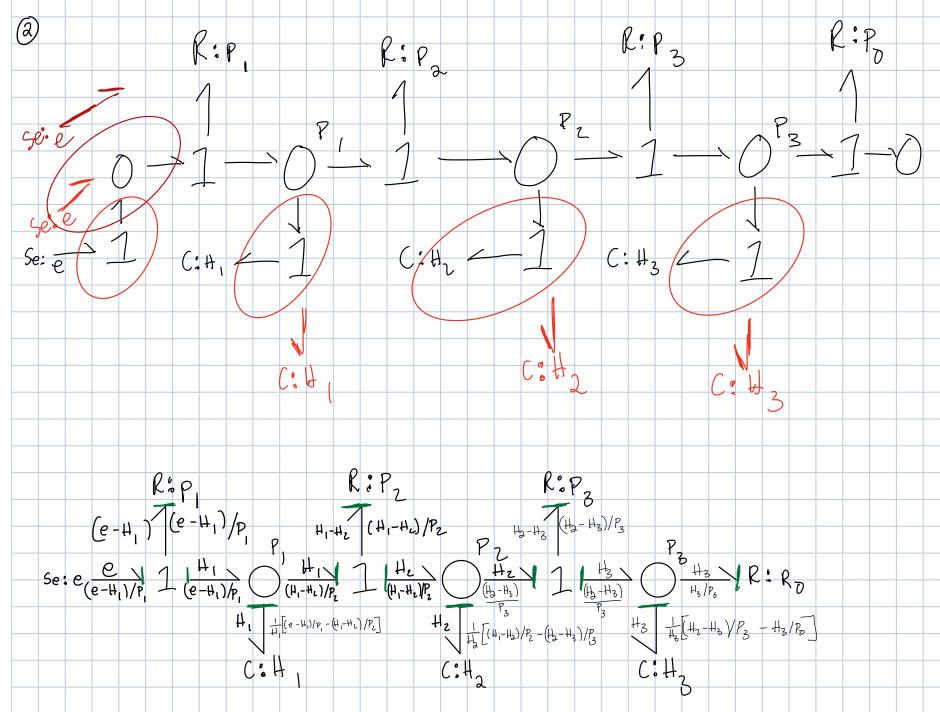

3.  **(10'') **

Find the state space model in matrix form.** (Be careful, if your state space model is wrong, then the entire simulation below will be incorrect)**

Define the A, B, C, and D matrices:

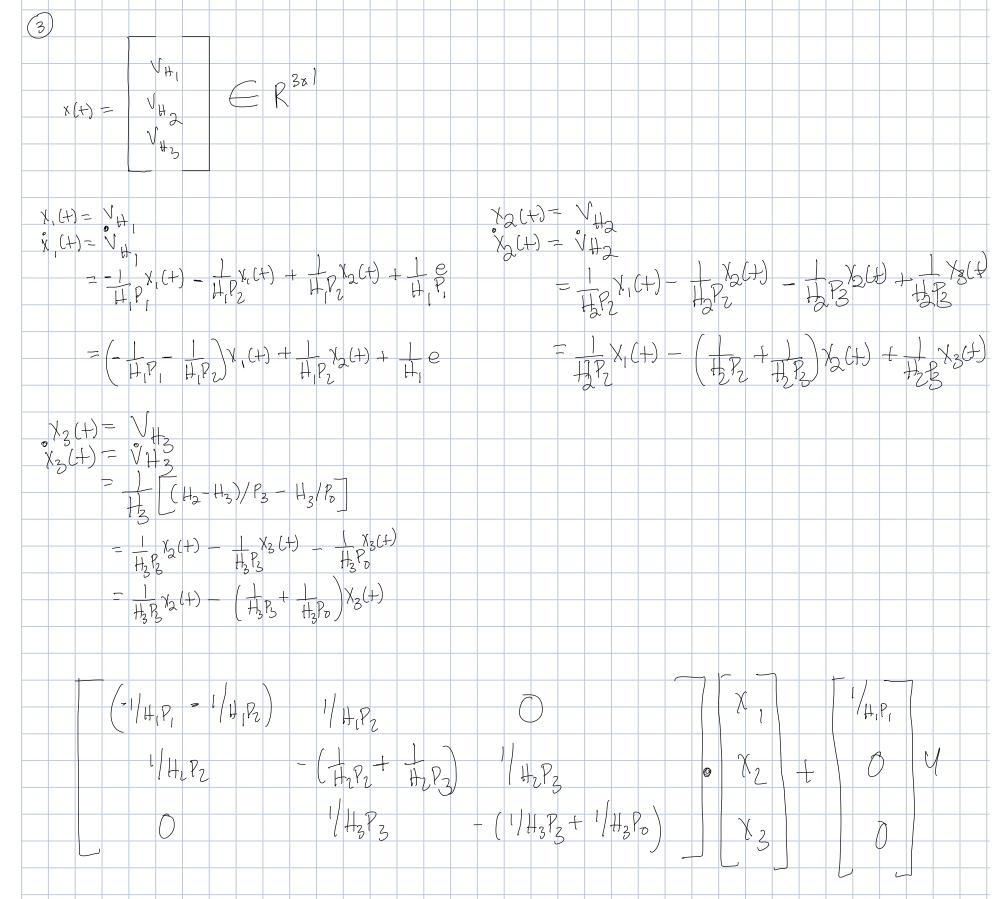

4. Correct the A, B, C, and D matrices in 'fluid_animation_init.m'

Then, run the file above. (Simulink file will be opened automatically)

R1 = 7.9577e+03

R2 = 1.5915e+04

R3 = 5.0301e+04

R0 = 2.5465e+05

C1 = 2.0408e-04

C2 = 5.1020e-05

C3 = 1.0204e-05

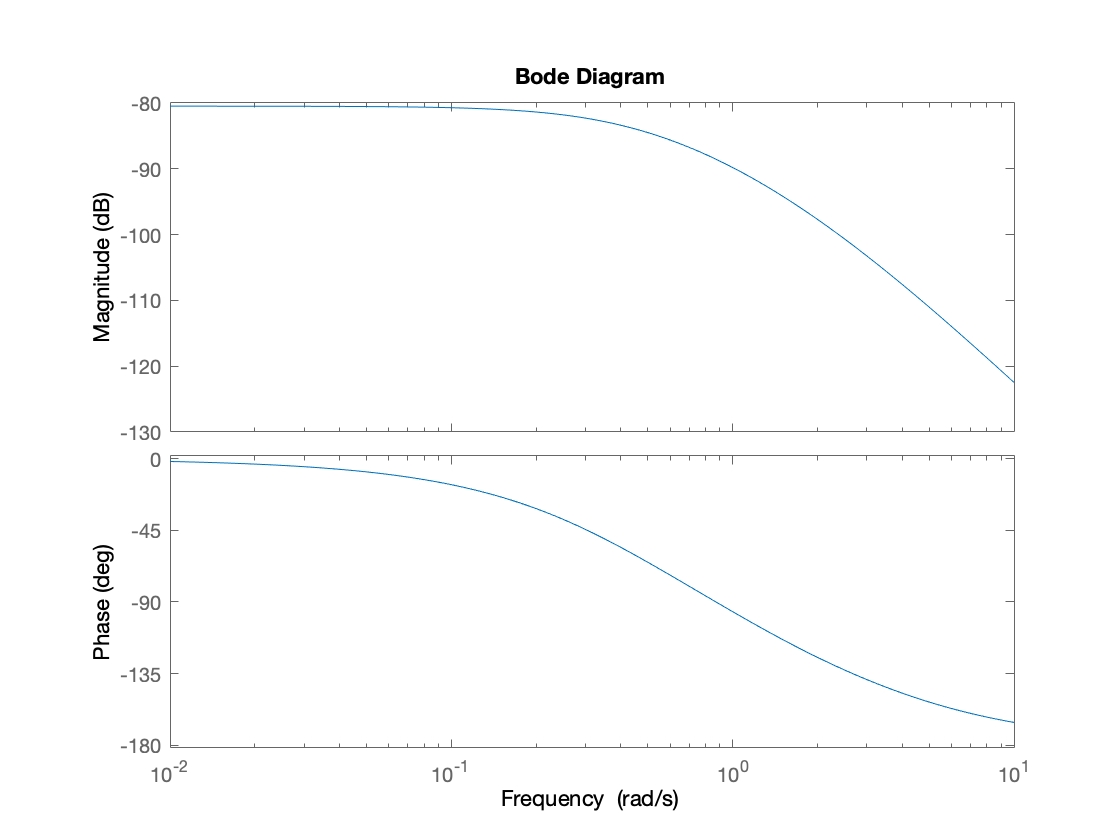

Undefined function or variable 'fluid_animated'.

Error in fluid_animation_init (line 73)
fluid_animated      % opens the simulink file

Error in run (line 91)
evalin('caller', strcat(script, ';'));

run fluid_animation_init.mlx;

**(10'')  **Display the output graph Qo. (No graph will be given for checking this time. Notice that no tank should overflow otherwise your simulation will show errors if the matrices not be set correctly.)

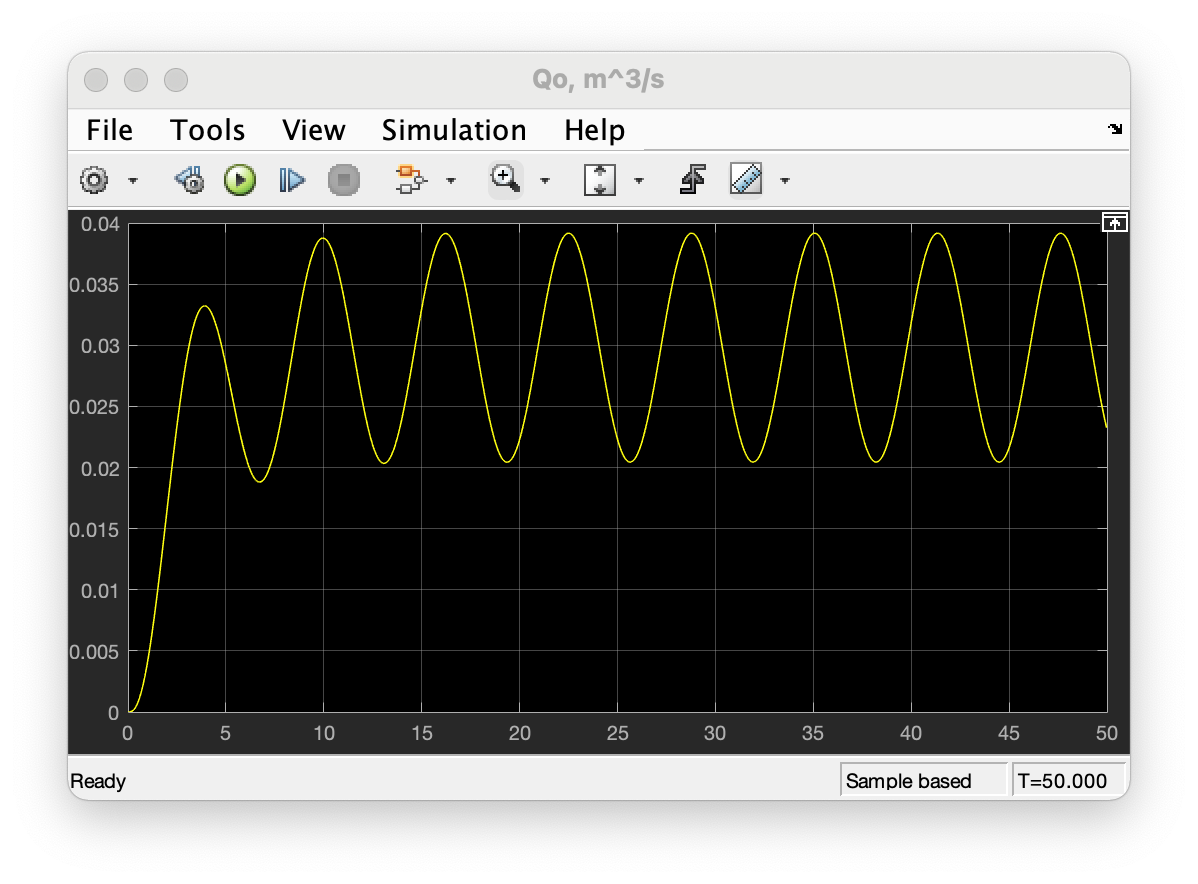

5.  Bode graph **(10'')**

w=logspace(-2,1,100);
% Please re-define the matrices C_Qo and D_Qo
C_Qo = [0 0 1/R0];
D_Qo = zeros(1,1);
% Because in this problem, it's to plot the magnitude of the transfer function from Pp
% to Qo. So, the output y = Qo.
sys = ss(A,B,C_Qo,D_Qo);
[mag, phase, omega] = bode(sys,w); % Get the data
figure
bode(sys,w); % Plot the gragh
grid on;

Using 'find' function. 

Find the minimum frequency where its magnitude <= mag(1)*1%.  **(5'')**

indx = find(abs(mag-mag(1)*0.01)<=(min(abs(mag-mag(1)*0.01))))

6. Go to 'fluid_animation_init.m',  set the value of ωo to the value that you compute from last step.

**(10'') **Display the output graph Qo. (No graph will be given for checking)

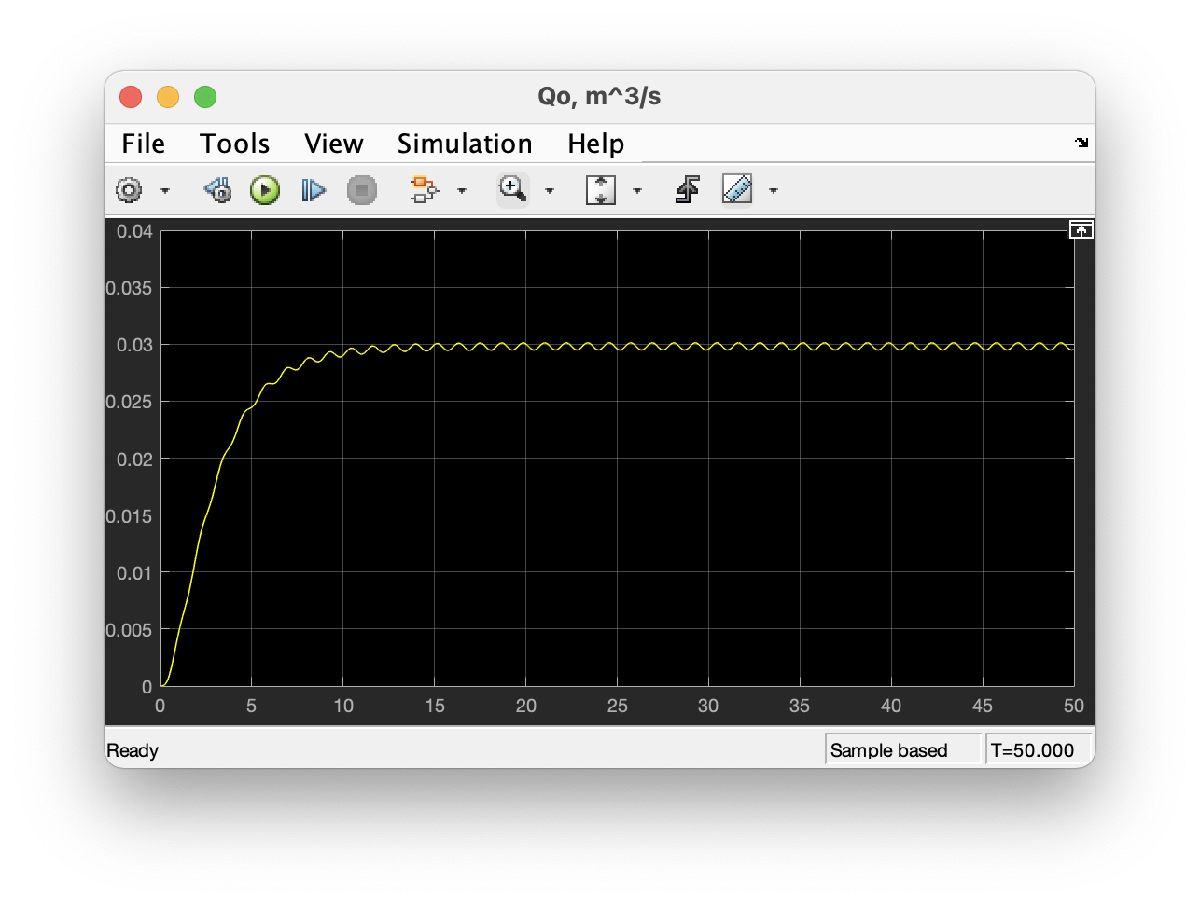

Using cursor measurement measure the max and min at the steady state flow.

Compute $\frac{\max -\min }{\left(\max +\min \right)/2}$. **(5'')**

max = 3.010e-02

min = 2.948e-02

Does this value approximately achieve 1%? **(5'')**

No, this value does not approximately achieve 1%. It is over by 1%. 

7.

For example, to compute the minimum height of H1 **(10'')**

% Get the magnitude information
sys = ss(A,B,C(1,:),D(1,:));
[magh1, phaseh1, omegah1] = bode(sys,w);
% the steady state amplitude at DC is magh1(1)
% and at ωo is magh1(ωo-1) where wo is the idex you get from step 5.
H1= (magh1(1) + magh1(indx(1)-1))*9800

Then compute H2 **(10'')**

sys = ss(A,B,C(2,:),D(2,:));
[magh2, phaseh2, omegah2] = bode(sys,w);
H2= (magh2(1) + magh2(indx(1)-1))*9800

and H3 **(10'')**.

sys = ss(A,B,C(3,:),D(3,:));
[magh3, phaseh3, omegah3] = bode(sys,w);
H3= (magh3(1) + magh3(indx(1)-1))*9800

Change the 'Height' in 'fluid_animation_init.m' using the value of H1, H2 and H3.

run fluid_animation_init.mlx;

Re-simulate. Do any tanks overflow? **(5'')**

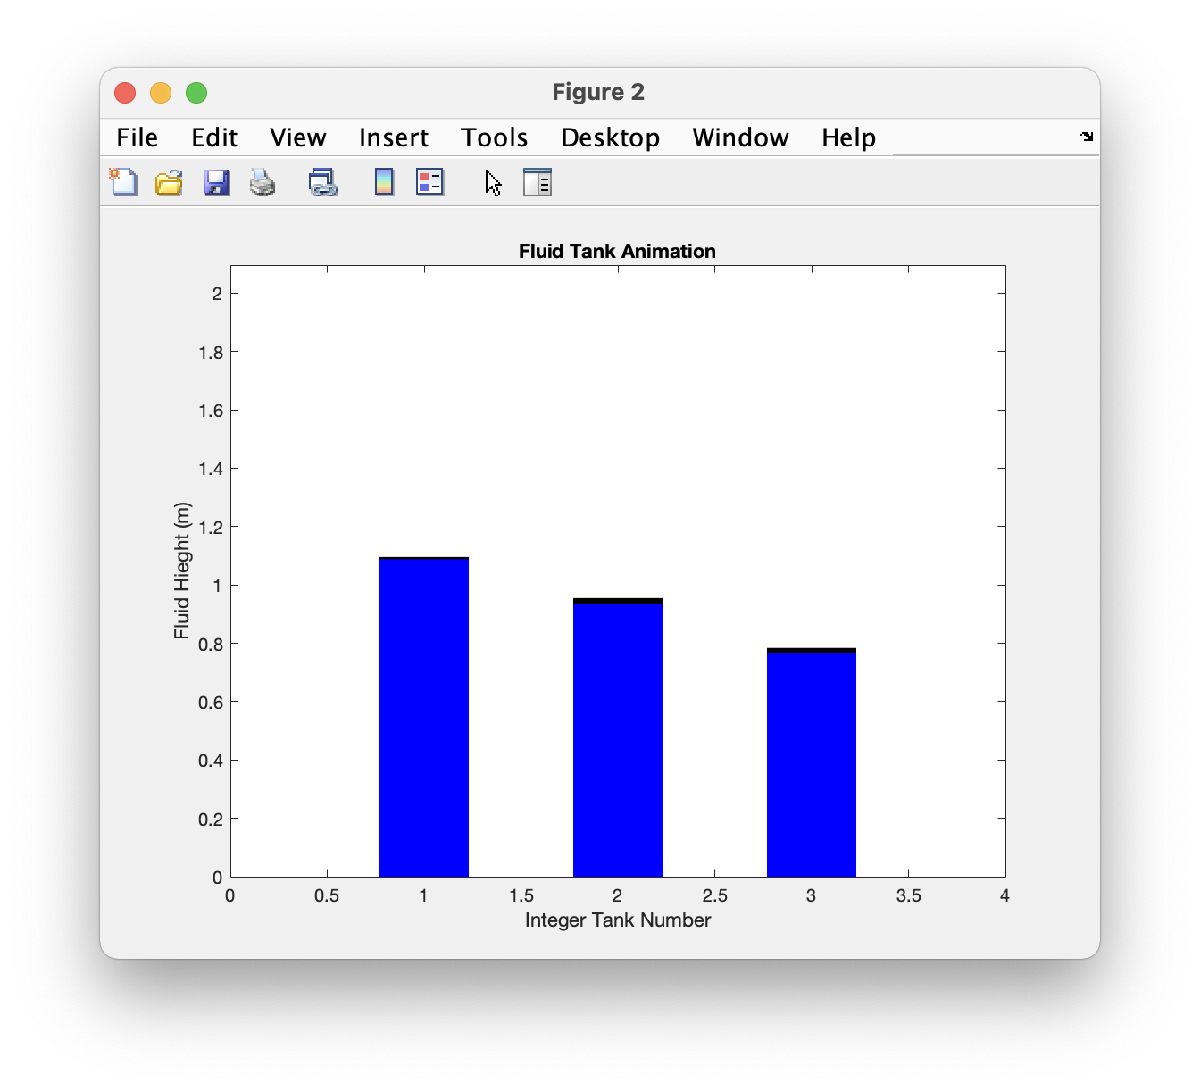

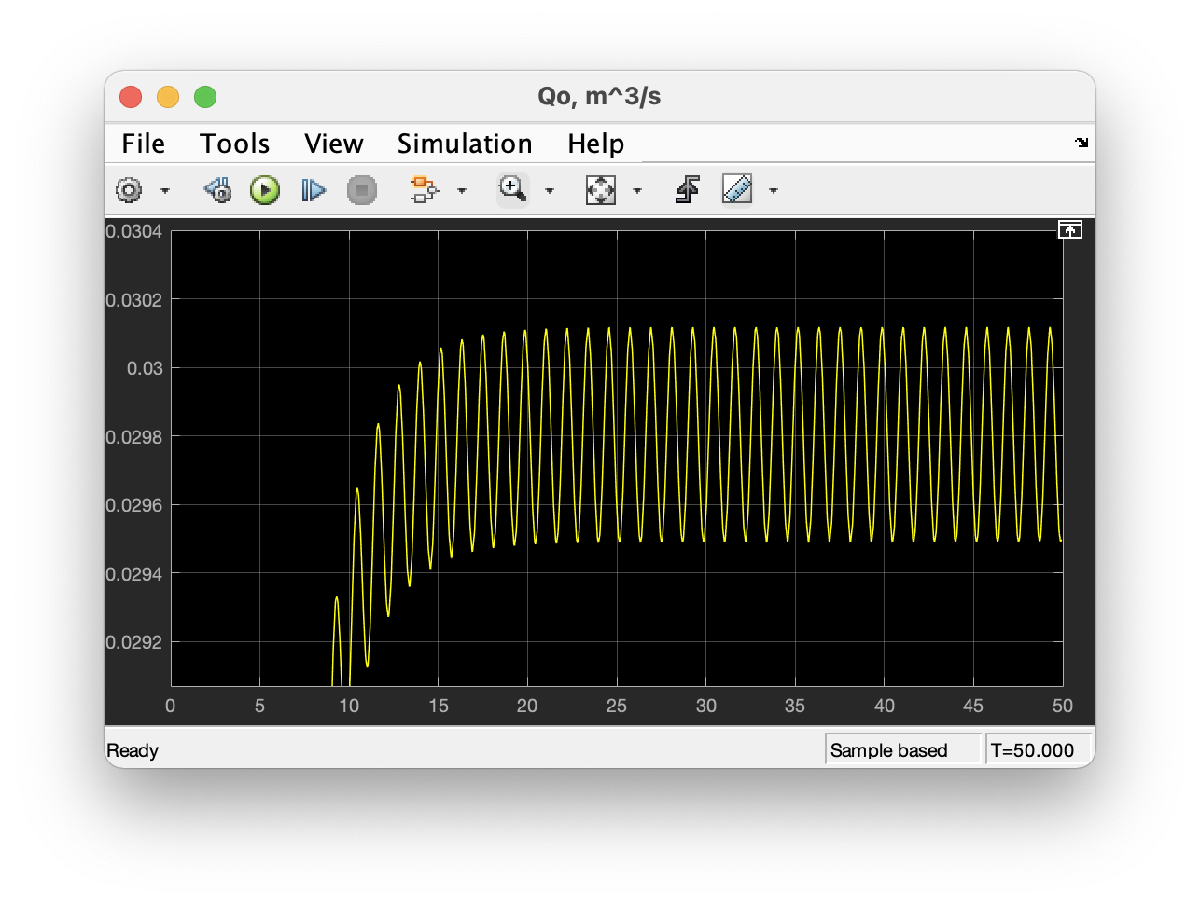

None of the tanks were overflown. 